**ENGN1930B Lab1**

**Instructor: Dr. Jonghwan Lee**

**Name: Kuan-Min Lee**

**(a)**

In this part of the experiment, the symbolic computation is implemented to computate function of z_foc.

To start with this, the symbolic computation is first implemented: 

clear all

syms z_src z_len f z positive % define z_src, z_len, and f as paratmeter
syms x_samp theta_samp positive % define the paramters and key variables for the function

assume(z_src>f)

rIn=[x_samp theta_samp]'; % define input light ray

Next, the RTM for air between the source and the first lens, first lens, air between the first and second lens, second lens, and the air after the second lens will be defined:

RTM_air_src_first=[1 z_src;0 1]; % RTM for air between the source and the first lens
RTM_first_lens=[1 0;-1/f 1]; % RTM for first lens
RTM_air_first_second=[1 z_len;0 1]; % RTM for air between the first and second lens
RTM_second_lens=[1 0;-1/f 1]; % RTM for second lens
RTM_air_second=[1 z;0 1]; % RTM for air after the second lens
RTM_sys=RTM_air_second*RTM_second_lens*RTM_air_first_second*RTM_first_lens*RTM_air_src_first; % RTM for the entire system

Next, we define the output light ray:

rOut=RTM_sys*rIn;

Then, we define the output function for x:

xOut(z,theta_samp,z_src,z_len,f,x_samp)=rOut(1);
xOutConc(z,z_src,z_len,f,x_samp)=xOut(z,0.1,z_src,z_len,f,0) % define the x difference function

$$xOutConc(z, z\_src, z\_len, f, x\_samp) = \frac{z}{10}-\frac{z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)}{10}-\frac{z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{10}$$

zsol(z_src,z_len,f)=solve(xOutConc==0,z) % solve for z (z_foc)

$$zsol(z\_src, z\_len, f) = \frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}$$

To comfirm the result from previous computation, a light source at position of x_samp, and angle of 0 and -0.1 rad is implemented. And the point where the light ray with these two different angles is observed:

xOut(z,theta_samp,z_src,z_len,f,x_samp)=rOut(1);
xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_src,z_len,f,x_samp/2)-xOut(z,-0.1,z_src,z_len,f,x_samp/2) % define the x difference function

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{z}{10}-\frac{z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)}{10}-\frac{z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{10}$$

zsol(z_src,z_len,f)=solve(xOutDiff==0,z) % solve for z (z_foc)

$$zsol(z\_src, z\_len, f) = \frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}$$

From the above the result, it can be seen that the results from the two are identical.

**(b):**

In this section, the magnification between the image on the focal plane and the original light source is observed.

To get the magnification ratio, x_foc needs computed:

x_foc=xOut(zsol(z_src,z_len,f),theta_samp,z_src,z_len,f,x_samp)

$$x\_foc = \begin{array}{l} x_{\mathrm{samp}}\,\sigma_{1}+\theta_{\mathrm{samp}}\,\left(\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}-z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)+z_{\mathrm{src}}\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)-\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}}{f}-\sigma_{2}+1\\ \sigma_{2}=\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)} \end{array}$$

Next, to get the maginfication ratio, it needs to be divided by the original x of light source:

m=x_foc/x_samp

$$m = \begin{array}{l} \frac{x_{\mathrm{samp}}\,\sigma_{1}+\theta_{\mathrm{samp}}\,\left(\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}-z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)+z_{\mathrm{src}}\,\sigma_{1}\right)}{x_{\mathrm{samp}}}\\ \mathrm{where}\\ \sigma_{1}=\frac{z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)-\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}}{f}-\sigma_{2}+1\\ \sigma_{2}=\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)} \end{array}$$

**(c):**

For this portion of the experiment, the relative value of magnification will be computed. 

To start with this portion, the zrel_src and zrel_foc is setup:

zrel_src=z_src/f; % set up z_rel_src
zrel_foc=zsol(z_src,z_len,f)/f % compute z_rel_foc function

$$zrel\_foc = \frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)}$$

x_foc=xOut(zrel_foc,theta_samp,zrel_src,z_len,f,x_samp)

$$x\_foc = \begin{array}{l} \theta_{\mathrm{samp}}\,\left(\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)}-z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)+\frac{z_{\mathrm{src}}\,\sigma_{1}}{f}\right)+x_{\mathrm{samp}}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)-\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)}}{f}-\sigma_{2}+1\\ \sigma_{2}=\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f^{2}\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)} \end{array}$$

**(d):**

For this portion of the expeirment, the effect of the deviation of LED position on the image formation will be observed.

To start with this problem, the z_rel_src values are set to be between 0.8 to 1.2, the focal point value is set to be 40 mm, and the z_len is set to be 1-, 2-, 3-, and 4-time the focal point value:

z_rel_src=[0.8 1.2]; % setup z_rel_src value
f1=40e3; % setup focal point length (40mm)
z_len_fact=[1 2 3 4]; % setup factor for z_len
num_z_rel_src=numel(z_rel_src);
num_fact=numel(z_len_fact);

figure(1);
z_len1=z_len_fact(1)*f1; % get the current z_len
xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_src,z_len1,f1,x_samp/2)-xOut(z,-0.1,z_src,z_len1,f1,x_samp/2); % define the x difference function
zsol(z_src)=solve(xOutDiff==0,z); % solve for z (z_foc)

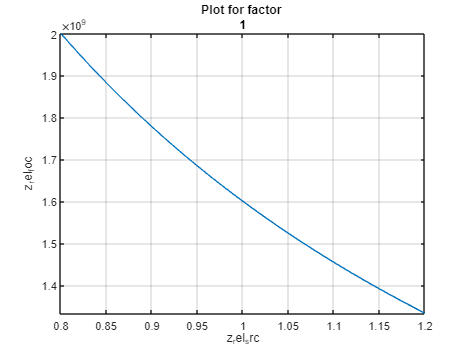

fplot(zsol(z_src),z_rel_src) % plot the z_foc vs z_src plot
grid on
graph_title=['Plot for factor ', string(1)];
title(graph_title);
xlabel('z_rel_src');
ylabel('z_rel_foc')

Then, the setup for plotting z_rel_foc over z_rel_src will be setup:

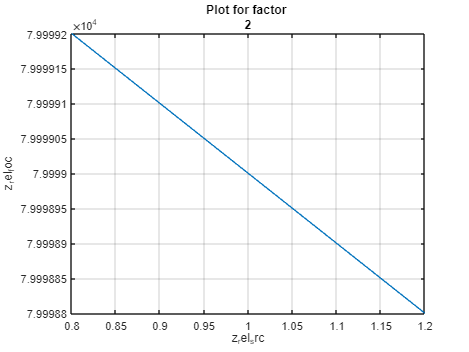

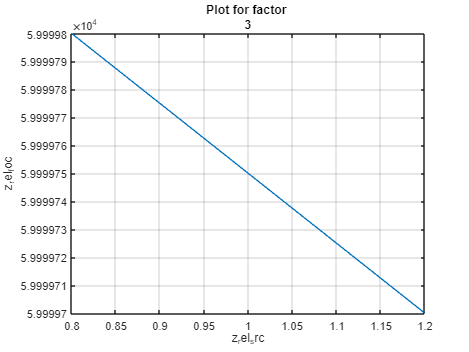

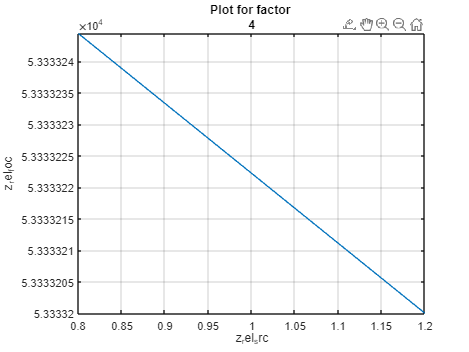

for i_fact=1:num_fact
    figure(i_fact);
    z_len1=z_len_fact(i_fact)*f1; % get the current z_len value
    xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_src,z_len1,f1,x_samp/2)-xOut(z,-0.1,z_src,z_len1,f1,x_samp/2); % define the x difference function
    zsol(z_src)=solve(xOutDiff==0,z); % solve for z (z_foc)
    fplot(zsol(z_src),z_rel_src) % plot for z_foc vs z_src plot
    grid on
    graph_title=['Plot for factor ', string(i_fact)];
    title(graph_title);
    xlabel('z_rel_src');
    ylabel('z_rel_foc')
end

From the graph shown above, it does show out the fact that as the z_rel_src decrease, the z_rel_foc will increase. Therefore, the plot matches the intuition mentioned in the question. Based on the theory of lens equation:

1/z_img = 1/f - 1/z_samp

the intuition that as the sample moves away, the image will becomes smaller should follow. 

To observe the effect of z_len, the similar procedure is followed again except for this time, the z_len is the controlled factor:

z_rel_src=0.8:0.2:1.2; % define the src controlled values
figure(1);
z_rel_src1=z_rel_src(1); % get the current z_src value
xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_rel_src1,z_len,f1,x_samp/2)-xOut(z,-0.1,z_rel_src1,z_len,f1,x_samp/2); % define the x difference function

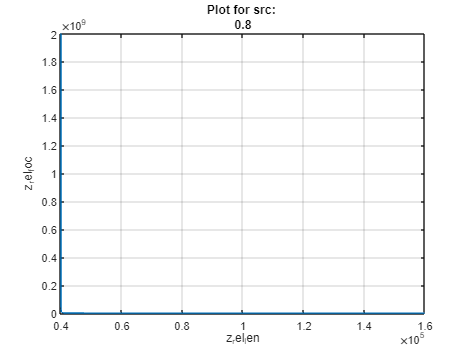

zsol(z_len)=solve(xOutDiff==0,z); % solve for z (z_foc)
fplot(zsol(z_len),z_lens) % plot the z_foc vs z_len plot
grid on
graph_title=['Plot for src: ', string(z_rel_src1)];
title(graph_title);
xlabel('z_rel_len');

ylabel('z_rel_foc')

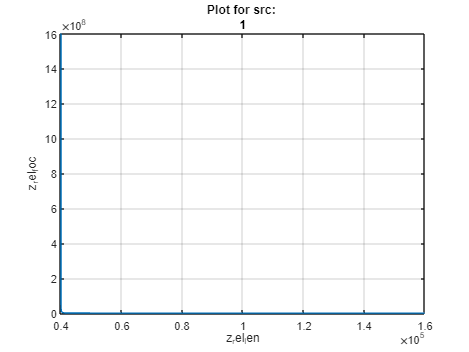

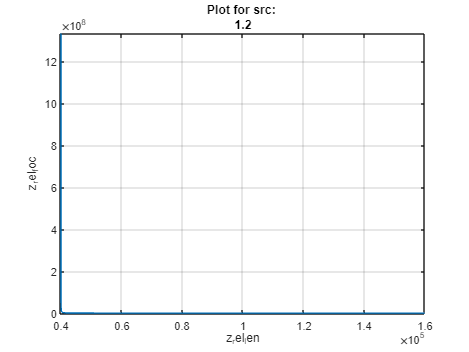

z_lens=[1*f1 4*f1]; % define the z_lens values
num_src=numel(z_rel_src);
for i_src=1:num_src
    figure(i_src);
    z_rel_src1=z_rel_src(i_src); % get the current z_src value
    xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_rel_src1,z_len,f1,x_samp/2)-xOut(z,-0.1,z_rel_src1,z_len,f1,x_samp/2); % define the x difference function
    zsol(z_len)=solve(xOutDiff==0,z); % solve for z (z_foc)
    fplot(zsol(z_len),z_lens) % plot the z_foc vs z_lens plot
    grid on
    graph_title=['Plot for src: ', string(z_rel_src1)];
    title(graph_title);
    xlabel('z_rel_len');
    ylabel('z_rel_foc')
end

From the above observation, as the distance between the lens increases, the focal point after the second the lens becomes smaller also. Contrast to the inverse linear proportion relationship found in the previous section, the relationship between z_foc and z_rel_len follows like a

**(e):**

For this portion of the experiment, the same plot will be generated except for this time, the observation is made on the magnification not z_rel_foc:

z_rel_src=[0.8 1.2];
figure(1);
z_len1=z_len_fact(1)*f1;
xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_src,z_len1,f1,x_samp/2)-xOut(z,-0.1,z_src,z_len1,f1,x_samp/2); % define the x difference function
zsol(z_src)=solve(xOutDiff==0,z); % solve for z (z_foc)

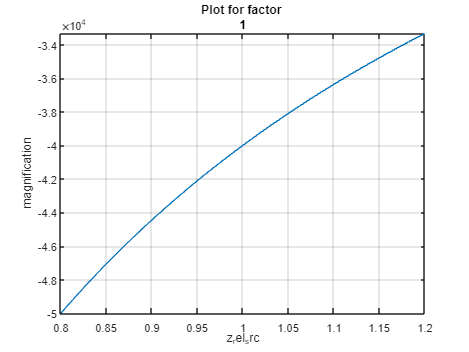

xOutImg(z_src)=xOut(zsol,0,z_src,z_len1,f1,x_samp)/x_samp;
fplot(xOutImg(z_src),z_rel_src)
grid on
graph_title=['Plot for factor ', string(1)];
title(graph_title);
xlabel('z_rel_src');
ylabel('magnification')

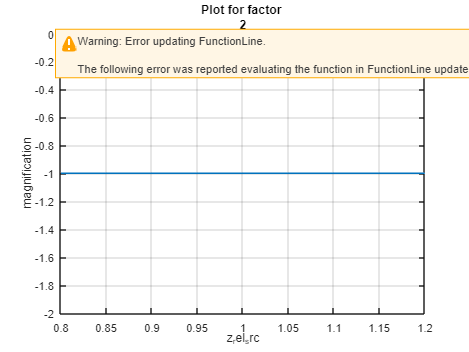

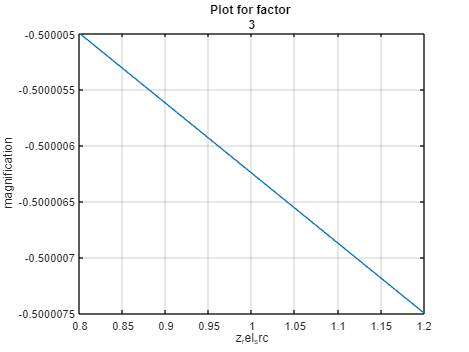

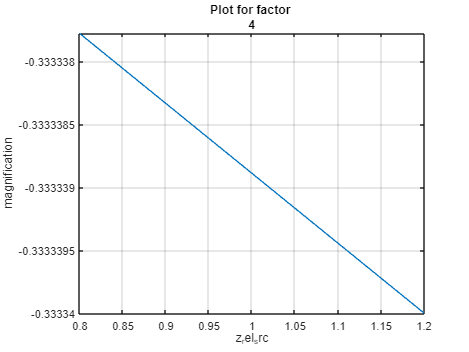

for i_fact=1:num_fact
    figure(i_fact);
    z_len1=z_len_fact(i_fact)*f1;
    xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_src,z_len1,f1,x_samp/2)-xOut(z,-0.1,z_src,z_len1,f1,x_samp/2); % define the x difference function
    zsol(z_src)=solve(xOutDiff==0,z); % solve for z (z_foc)
    xOutImg(z_src)=xOut(zsol,0,z_src,z_len1,f1,x_samp)/x_samp;
    fplot(xOutImg(z_src),z_rel_src)
    grid on
    graph_title=['Plot for factor ', string(i_fact)];
    title(graph_title);
    xlabel('z_rel_src');
    ylabel('magnification')
end

For the observation of the effect of z_lens, 

z_rel_src=0.8:0.2:1.2;
z_lens=[1*f1 4*f1];
figure(1);
z_rel_src1=z_rel_src(1);
xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_rel_src1,z_len,f1,x_samp/2)-xOut(z,-0.1,z_rel_src1,z_len,f1,x_samp/2); % define the x difference function
zsol(z_len)=solve(xOutDiff==0,z); % solve for z (z_foc)

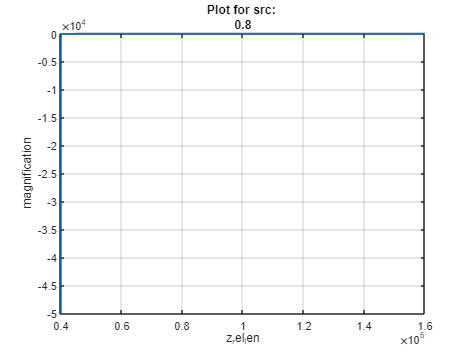

xOutImg(z_len)=xOut(zsol,0,z_rel_src1,z_len,f1,x_samp)/x_samp;
fplot(xOutImg(z_len),z_lens)
grid on
graph_title=['Plot for src: ', string(z_rel_src1)];
title(graph_title);
xlabel('z_rel_len');
ylabel('magnification')

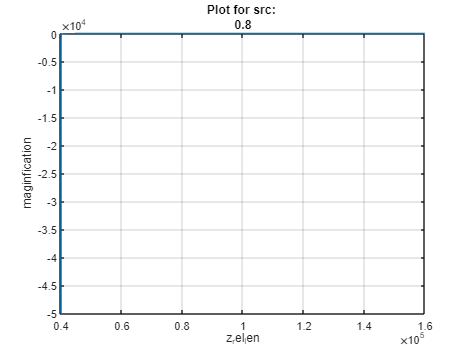

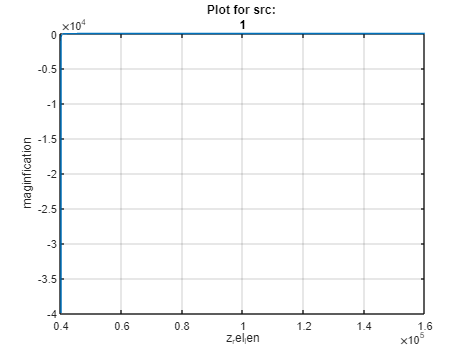

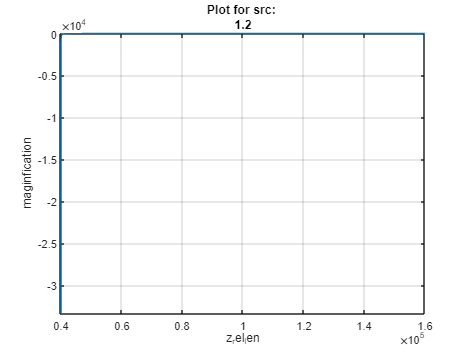

z_rel_src=0.8:0.2:1.2;
num_src=numel(z_rel_src);
for i_src=1:num_src
    figure(i_src);
    z_rel_src1=z_rel_src(i_src);
    xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_rel_src1,z_len,f1,x_samp/2)-xOut(z,-0.1,z_rel_src1,z_len,f1,x_samp/2); % define the x difference function
    zsol(z_len)=solve(xOutDiff==0,z); % solve for z (z_foc)
    xOutImg(z_len)=xOut(zsol,0,z_rel_src1,z_len,f1,x_samp)/x_samp;
    fplot(xOutImg(z_len),z_lens)
    grid on
    graph_title=['Plot for src: ', string(z_rel_src1)];
    title(graph_title);
    xlabel('z_rel_len');
    ylabel('maginfication')
end

 From the above observation, it can be seen that the case of 2*f varies the magnification the least. Therefore, it can be the optimal z_rel_lens value.

**(f):**

For this protion, the following assumptions are made:

- LED light is a point source

- LED has a specific diverging angle and its emission is uniform

and we need to find the power collection efficiency defined as the ratio of the collected light power to the original light power.

syms z_src f x_aper positive % define z_src, z_len, and f as paratmeter
syms theta_samp positive

x_samp1=0; % sample is centered (x=0)
theta_samp1=1.12; % diverging angle as 1.12 radius
f1=40e3; % focal length as 40mm
x_aper1=20e3

x_aper1 = 20000

z_rel_src=[0.8 1.2];

pce(z_src,f,x_aper,theta_samp)=sin(atan(x_aper/z_src))/sin(theta_samp)

$$pce(z\_src, f, x\_aper, theta\_samp) = \frac{x_{\mathrm{aper}}}{z_{\mathrm{src}}\,\sin\left(\theta_{\mathrm{samp}}\right)\,\sqrt{\frac{{x_{\mathrm{aper}}}^{2}}{{z_{\mathrm{src}}}^{2}}+1}}$$

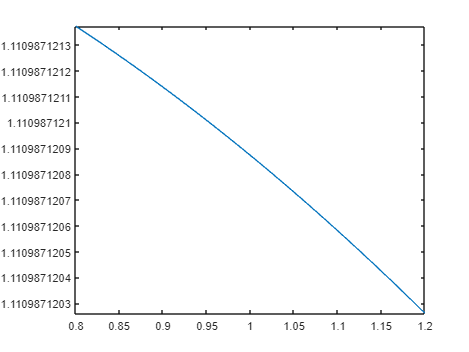

pce_out(z_src)=pce(z_src,f1,x_aper1,theta_samp1);
fplot(pce_out(z_src),z_rel_src)

Based on the observation from the plot above, as the distance ofthe source increases, the power collection efficiency does decreases.

**(g):**

For this portion of the problem, the secondary power loss is considered into the same environment as the first problem:

pce_out2(z_src,f,x_aper,theta_samp)=sin(theta_samp)/sin(atan(x_aper/z_src)+atan(x_aper/f))

$$pce\_out2(z\_src, f, x\_aper, theta\_samp) = \frac{\sin\left(\theta_{\mathrm{samp}}\right)}{\sin\left(\mathrm{atan}\left(\frac{x_{\mathrm{aper}}}{z_{\mathrm{src}}}\right)+\mathrm{atan}\left(\frac{x_{\mathrm{aper}}}{f}\right)\right)}$$

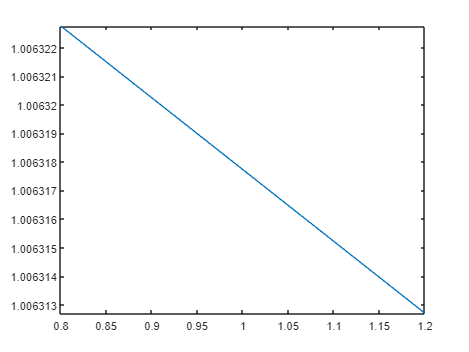

pce_out2(z_src)=pce_out2(z_src,f1,x_aper1,theta_samp1);
fplot(pce_out2(z_src),z_rel_src)

From the above outcome, it can be seen that the outcome between the two sections match to each other.

**(h):**

For this protion of the experiment, we would like to find the point where the z score:

Z = (power collection efficiency) * (secondary power collection efficiency) / (magnification)2

is maximized.

syms x_samp z
z_len1=11e3 % lens travel range

z_len1 = 11000

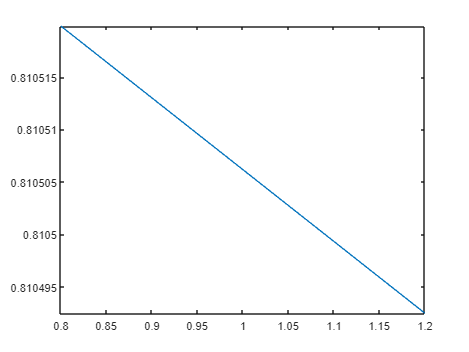

xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,theta_samp1,z_src,z_len1,f1,x_samp/2)-xOut(z,-theta_samp1,z_src,z_len1,f1,x_samp/2); % define the x difference function
zsol(z_src)=solve(xOutDiff==0,z); % solve for z (z_foc)
xOutImg(z_src)=xOut(zsol,0,z_src,z_len1,f1,x_samp)/x_samp;
pce_entire(z_src)=pce_out(z_src)*pce_out2(z_src);
z_scroe(z_src)=pce_entire(z_src)/xOutImg(z_src);
fplot(z_scroe(z_src),z_rel_src)

From the above plot, the closer it is to the lens the better, which match the intuition from the previous section.